load quadraticSVM.mat;

path = uigetdir();
imageFiles = dir(strcat(path, '/*.png'))

imageFiles = 20×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


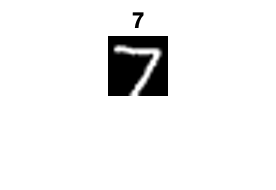

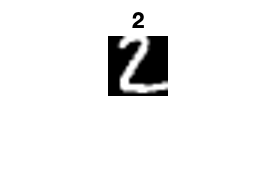

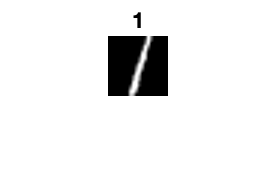

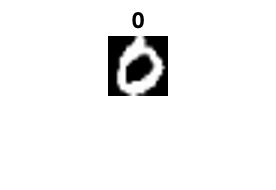

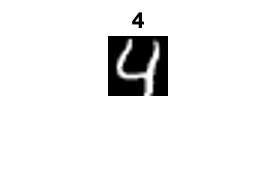

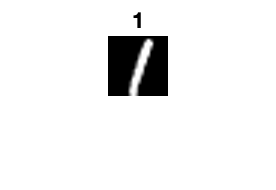

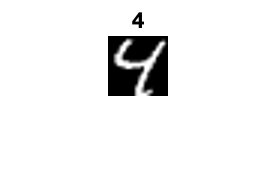

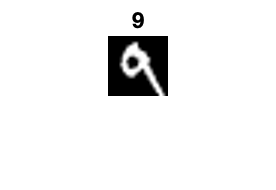


for i = 1:length(imageFiles)
    img = imread(strcat(imageFiles(i).folder, '/', imageFiles(i).name));
    prediction = predictDigit(img, quadraticSVM);
    
    figure
    showImage = imresize(img, 3);
    imshow(showImage), title(prediction);
    hold on
end